## BOW Physiognomy

Sam Coleman and Caitlin Kantor

clear vars
clear
clf
clc
% MAYBE TRY non negative matrix factorization
% Create matrices for each institution
%commented out because we loaded it into a mat file

% for k = 1:75
%     pngFilename = sprintf('Br%d.png', k);    
%     fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         B = double(rgb2gray(imread(fullFileName)))/255.0;
%         %B = double(imread(fullFileName));
%         %B = rgb2gray(B);
%         B = reshape(B, [], 1);
%     end
%     Ball(:, k) = B;
% end
% 
% for k = 1:75
%     pngFilename = sprintf('Or%d.png', k);
%     fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         O = double(rgb2gray(imread(fullFileName)))/255.0;
%         O = reshape(O, [], 1);
%     end
%     Oall(:, k) = O;
% end
% 
% for k = 1:75
%     pngFilename = sprintf('Wr%d.png', k);
%     fullFileName = fullfile('C:\Users\scoleman\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         W = double(rgb2gray(imread(fullFileName)))/255.0;
%         W = reshape(W, [], 1);
%     end
%     Wall(:, k) = W;
% end
% 
% save('TrainingData.mat', 'Ball', 'Oall', 'Wall')

% load B, O, W training data matrices
load TrainingData.mat

scaleFactor = 25;
locationFactor = -.5*scaleFactor;

for i=1:75
    i
    Babson = reshape(Ball(:, i), [100 100]);
    size(Babson);
    faceDetector = vision.CascadeObjectDetector;
    Testbox = step(faceDetector, Babson); %+ [locationFactor locationFactor scaleFactor scaleFactor];
    %imagesc(Babson)
    %colormap('gray')
    vision.ShapeInserter('BorderColor', 'Custom', 'CustomBorderColor',[255 255 0]);
    TestFaces = step(vision.ShapeInserter, Babson, int32(Testbox)); 
    figure, imagesc(TestFaces), title('Detected faces');
    colormap('gray')
    axis 'square'
    
    BabsonCrop = imcrop(Babson, Testbox);
    imshow(BabsonCrop);
    BabsonCrop = imresize(BabsonCrop, [75 75]);
    imwrite(BabsonCrop, sprintf('BrC%d.png', i))
end

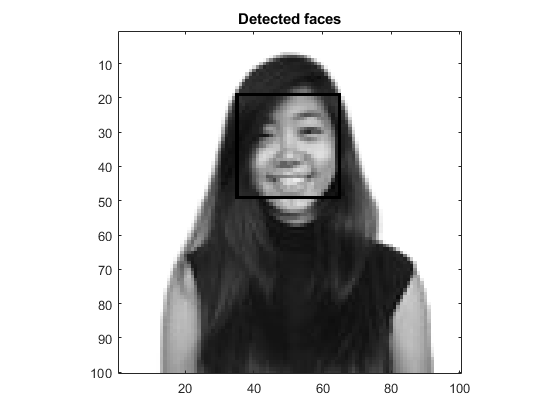

    Babson = reshape(Ball(:, 7), [100 100]);
    size(Babson);
    faceDetector = vision.CascadeObjectDetector;
    Testbox = step(faceDetector, Babson); %+ [locationFactor locationFactor scaleFactor scaleFactor];
    %imagesc(Babson)
    %colormap('gray')
    vision.ShapeInserter('BorderColor', 'Custom', 'CustomBorderColor',[255 255 0]);
    TestFaces = step(vision.ShapeInserter, Babson, int32(Testbox)); 
    figure, imagesc(TestFaces), title('Detected faces');
    colormap('gray')
    axis 'square'

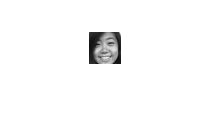

    
    BabsonCrop = imcrop(Babson, Testbox);
    imshow(BabsonCrop);

%Turn matrices into column vectors
%BCol = reshape(B, [100*100, 75])';
BCol = Ball';
OCol = Oall';
WCol = Wall';
% OCol = reshape(O, [100*100, 75])';
% WCol = reshape(W, [100*100, 75])';

%Make mean centered
BCol = BCol - mean(BCol);
OCol = OCol - mean(OCol);
WCol = WCol - mean(WCol);

AllCol = cat(1, BCol, OCol, WCol);

%Find covariance matrices
Ba = (1/sqrt(9999)) * BCol;
Br = Ba' * Ba;
Oa = (1/sqrt(9999)) * OCol;
Or = Oa' * Oa;
Wa = (1/sqrt(9999)) * WCol;
Wr = Wa' * Wa;


Aa = (1/sqrt(9999)) * AllCol;
Ar = Aa' * Aa;

%Find eigenvectors (and values)
[BV, BD] = eigs(Br, 40);
Bbodies = BV;
[OV, OD] = eigs(Or, 40);
Obodies = OV;
[WV, WD] = eigs(Wr, 40);
Wbodies = WV;

%Average all eigenbodies for BOW
avgBBodies = Bbodies(:, 1);
for i = 2:40
    avgBBodies = imadd(avgBBodies, Bbodies(:, i));
end

avgBBodies = avgBBodies / 40;
imshow(reshape(avgBBodies, [100 100]), [])


avgOBodies = Obodies(:, 1);
for i = 2:40
    avgOBodies = imadd(avgOBodies, Obodies(:, i));
end

avgOBodies = avgOBodies / 40;
imshow(reshape(avgOBodies, [100 100]), [])

avgWBodies = Wbodies(:, 1);
for i = 2:40
    avgWBodies = imadd(avgWBodies, Wbodies(:, i));
end

avgWBodies = avgWBodies / 40;
imshow(reshape(avgWBodies, [100 100]), [])

b_train1 = BCol * avgBBodies;
o_train1 = OCol * avgOBodies;
w_train1 = WCol * avgWBodies;


avgAllBodies = cat(2, avgBBodies, avgOBodies, avgWBodies)

[AV, AD] = eigs(Ar, 100);
AllBodies = AV;

%See the eigenbodies
% for i = 1:40
%     figure()
%     hold on
%     imagesc(reshape(AllBodies(:, i), [100, 100]))
%     colormap('gray')
%     axis ij
%     hold off
% end

%Create into body space
b_train = BCol * Bbodies;
o_train = OCol * Obodies;

w_train = WCol * Wbodies;

all_train = AllCol * AllBodies;

%Prepare Test Data
% counter = 0
% for k = 76:100
%     counter = counter + 1;
%     pngFilename = sprintf('Br%d.png', k);    
%     fullFileName = fullfile('C:\Users\ckantor\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         BOW_test = double(rgb2gray(imread(fullFileName)))/255.0;
%         %B = double(imread(fullFileName));
%         %B = rgb2gray(B);
%         BOW_test = reshape(BOW_test, [], 1);
%     end
%     BOW_test_all(:, counter) = BOW_test;
% end
% 
% counter = 25
% for k = 76:100
%     counter = counter + 1;
%     pngFilename = sprintf('Or%d.png', k);    
%     fullFileName = fullfile('C:\Users\ckantor\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         BOW_test = double(rgb2gray(imread(fullFileName)))/255.0;
%         %B = double(imread(fullFileName));
%         %B = rgb2gray(B);
%         BOW_test = reshape(BOW_test, [], 1);
%     end
%     BOW_test_all(:, counter) = BOW_test;
% end
% 
% counter = 50
% for k = 76:100
%     counter = counter + 1
%     pngFilename = sprintf('Wr%d.png', k);    
%     fullFileName = fullfile('C:\Users\ckantor\MATLAB Drive\Everything', pngFilename);
%     if exist(fullFileName, 'file')
%         BOW_test = double(rgb2gray(imread(fullFileName)))/255.0;
%         %B = double(imread(fullFileName));
%         %B = rgb2gray(B);
%         BOW_test = reshape(BOW_test, [], 1);
%     end
%     BOW_test_all(:, counter) = BOW_test;
% end
% 
% %Babson is 0, Olin is 1, Wellesley is 2 in answer matrix
% answerMatrix = ones([75 1]);
% counter = 0;
% for k = 1:25
%     counter = counter + 1;
%     answerMatrix(counter, 1) = 0;
% end
% 
% counter = 50;
% for k = 1:25
%     counter = counter + 1;
%     answerMatrix(counter, 1) = 2;
% end

%save('Bow_test_data.mat', 'BOW_test_all', 'answerMatrix')

%Load test data
load Bow_test_data.mat

%Prepare test data for anaylsis
BOW_test_all = BOW_test_all - mean(BOW_test_all);
%BOW_test_all = BOW_test_all';
bow_test = BOW_test_all' * AllBodies;

results = knnsearch(all_train, bow_test)
for i = 1:75
    results(i) = idivide(int16(results(i)), int16(75));
end

for i = 1:75
    if results(i) == 3
        results(i) = 2;
     end
end
results

accuracy = mean(answerMatrix == results)

% %Create plot for #principal components vs accuracy
% accuracies1 = ones(75, 1);
% for i = 1:225
%     i
%     [AV1, AD1] = eigs(Ar, i);
%     AllBodies1 = AV1;
%     all_train1 = AllCol * AllBodies1;
%     BOW_test_all1 = BOW_test_all - mean(BOW_test_all);
%     bow_test1 = BOW_test_all1' * AllBodies1;
%     
%     results = knnsearch(all_train, bow_test);
%     for k = 1:75
%         results(k) = idivide(int16(results(k)), int16(75));
%     end
% 
%     for k = 1:75
%         if results(k) == 3
%             results(k) = 2;
%         end
%     end
%     accuracies1(i) = mean(answerMatrix == results);
% end

%Create a box around faces
scaleFactor = 25;
locationFactor = -.5*scaleFactor;
test = reshape(Ball(:, 20), [100 100]);
size(test);
faceDetector = vision.CascadeObjectDetector;
Testbox = step(faceDetector, test) %+ [locationFactor locationFactor scaleFactor scaleFactor];
imagesc(test)
colormap('gray')
vision.ShapeInserter('BorderColor', 'Custom', 'CustomBorderColor',[255 255 0]);
TestFaces = step(vision.ShapeInserter, test, int32(Testbox)); 
figure, imagesc(TestFaces), title('Detected faces');
colormap('gray')
axis 'square'

testCrop = imcrop(test, Testbox);
imshow(testCrop)